R = 47

L = 4.7000e-05

vin = 1

g1 =
 
        47
  --------------
  4.7e-05 s + 47
 
Continuous-time transfer function.



t = 1.0e-05 *

         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


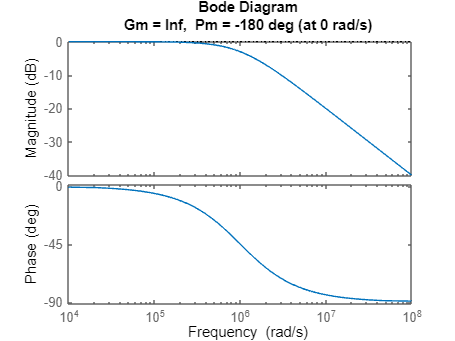


ans =

  0×1 empty double column vector



ans = -1.0000e+06

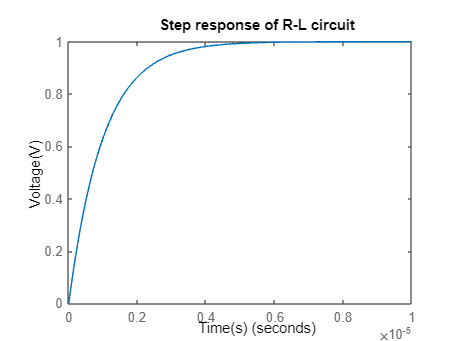

R2 = 230

L2 = 4.7000e-05

C2 = 1.0000e-08

Vin = 1

g =
 
               1
  ---------------------------
  4.7e-13 s^2 + 2.3e-06 s + 1
 
Continuous-time transfer function.



t1 = 1.0e-04 *

         0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0046    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0080    0.0082    0.0084    0.0086    0.0088    0.0090    0.0092    0.0094    0.0096    0.0098


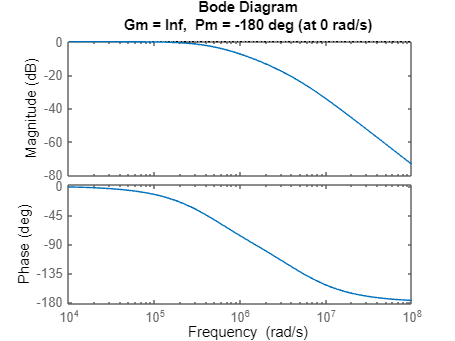


ans =

  0×1 empty double column vector



ans = 1.0e+06 *

   -4.4113
   -0.4823


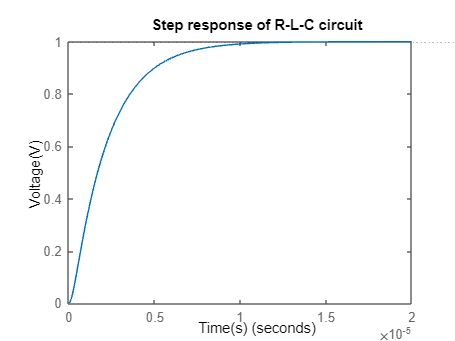

% Define the inductance and voltage input for the R-L circuit
L = 47e-6; % inductance in Henries

vin = 1;   % voltage input

% Calculate the transfer function (g1) of the R-L circuit using the resistor R and vector [L R] for coefficients
R = 47;    % resistance in ohms
g1 = tf(R , [L R]);

% Define the time vector for simulation using the linspace function
t = linspace (0, 10e-6, 1000);

% Generate a vector of ones to use as the voltage input for the R-L circuit
Vin = ones(size(t));

% Plot the Bode plot of the transfer function
margin(g1);

% Plot the zeros and poles of the transfer function
zero(g1)
pole(g1)

% Plot the step response of the R-L circuit using the step function
step(g1, t);

% Add a title, x-axis label, and y-axis label to the plot
title('Step response of R-L circuit' )
xlabel('Time (s)');
ylabel('Voltage (V)');

% Define the parameters for the R-L-C circuit
R2 = 230;           % resistance in ohms
L2 = 47e-6;         % inductance in Henries
C2 = 10e-9;         % capacitance in Farads
Vin = 1;            % voltage input

% Calculate the transfer function (g) of the R-L-C circuit using the coefficients of the R, L, and C elements
g = tf(1, [L2*C2 R2*C2 1]);

% Define the time vector for simulation using the linspace function
t1 = linspace(0, 20e-6, 1000);

% Generate a vector of ones to use as the voltage input for the R-L-C circuit
Vin = ones(size(t1));

% Plot the Bode plot of the transfer function
margin(g);

% Plot the zeros and poles of the transfer function
zero(g)
pole(g)

% Plot the step response of the R-L-C circuit using the step function
step(g, t1);

% Add a title, x-axis label, and y-axis label to the plot
title('Step response of R-L-C circuit')
xlabel('Time (s)');
ylabel('Voltage (V)');

% This code doesn't include a low pass filter, so there's no need to add comments for it.
